# Figure 2C

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';


load([dataDir filesep 'A039_data.mat'],'S','settings','allIF');
conditions = settings.conditions

 framesPerHr = 60/12;
 frameEdU = 0;
 timeStart = 0;
 folding =5;
 numFrames = size(S(1).area,2);
 xFrames = 1:numFrames;
 xTime = (xFrames-1)./framesPerHr;

 times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
 [S.POI_time] = times{:};

 for i = 1:length(S)
      S(i).POI_realtime = S(i).POI/framesPerHr;
     end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcGate = false(length(dat.POI(:,1)),1);
    dbf4Gate = false(length(dat.POI(:,1)),1);
    dbf4level = NaN*ones(length(dat.POI(:,1)),1);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 5 & dat.POI(n,1) + 7 < numFrames
            apcGate(n) = dat.apcAreaNorm(n,dat.POI(n,1) - 5) > .4 & ...
                dat.apcAreaNorm(n,dat.POI(n,1) +7) < .1 ;
        end

         if dat.POI(n,2) > 1 * framesPerHr & dat.POI(n,2) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcNormM(n,dat.POI(n,2) + [-1* framesPerHr: -.5* framesPerHr] )) < .2 & ...
                nanmean(dat.apcNormM(n,dat.POI(n,2) + [round(.5* framesPerHr): 1* framesPerHr] )) > .1;
         end

        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            dbf4Gate(n) = nanmean(dat.sigNorm(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .9 & ...
              nanmean(dat.sigNorm(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] ))< 1;

        end

    end
    S(i).apcGate = apcGate;
   S(i).dbf4Gate = dbf4Gate;
    S(i).dbf4level = dbf4level;
     S(i).apcExpressGate = apcExpressGate;
end

conds=[2 14];
colors = [.1 .4 1; 0 .8 1;.5 .1 1;.333 .302 .541;.51 .008 .388;.851 .012 .408;.941 .447 .282;.333 .302 .541; 1 .831 0; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
POI_align = 3;
rng(10)
ally = [];
groups = [];
timeGate = [8 10];

for i=1:length(conds)
    yvals=[];
    c = conds(i);
    data = S(c);
      inds = ~isnan(S(conds(i)).POI(:,1))& ~isnan(S(conds(i)).POI(:,2)) &...
          (S(conds(i)).POI(:,1))>20& S(conds(i)).POI(:,2) > ((S(conds(i)).POI(:,1))+21) &...
           S(conds(i)).POI(:,2)+40<numFrames-10 &...
          S(conds(i)).POI(:,1)+10<numFrames-10  & (isnan(S(conds(i)).POI(:,6))|( S(conds(i)).POI(:,6)>  S(conds(i)).POI(:,2)+50));

 
sum(inds)
cells=find(inds);
    

      ydata= NaN*ones(length(S(conds(i)).POI(inds,1)),1);
      ydata2 = NaN*ones(length(S(conds(i)).POI(inds,2)),1);
   
      apc_POI = S(conds(i)).POI(inds,2);
       mitosis_POI = S(conds(i)).POI(inds,1);
       ydata_sig = (S(conds(i)).sigNuc(inds,:));
       
        
       for n = 1:size(apc_POI ,1)

         ydata(n) =  ydata_sig(n, mitosis_POI(n)+20);

          ydata2(n)=  ydata_sig(n, apc_POI(n)+20);
       end 


yvals =((ydata2-ydata)./ydata)*100;
 yvals = yvals( yvals<700 &yvals>-200);

yvals=randsample(yvals,min([200 length(yvals)]));

    ally = [ally; yvals];
  groups = [groups; repmat(i,size(yvals))];

    length(yvals)
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
     
end

ans = 10198

ans = 200

ans = 1324

ans = 200

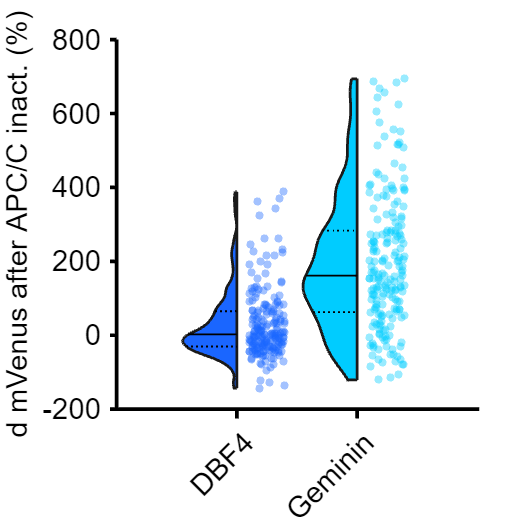



figure('Units', 'Inches', 'Position', [0, 0, 4, 4])

h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',1.5,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.4);
ylabel([ 'd mVenus after APC/C inact. (%)'])
xticklabels({'DBF4','Geminin'})
xtickangle(45)

p=mediantest(ally(groups==1),ally(groups==2))

p = 1.1259e-22

% print_pdf('2C_DBF4_gem_violin.pdf')
